# Exercise B | Beam analysis with the stiffness method

This lesson links the mechanics of a continuous beam to each step of a matrix-based MATLAB solution. Read the explanation, inspect the code, and then run the section. Use Run All for the complete solution, or run the sections in order: later sections reuse variables created earlier.

Problem: an 18 m continuous beam has fixed ends at x = 0 and 18 m and a roller at x = 11 m. Uniform downward loads are 30 kN/m on the 11 m span and 44 kN/m on the 7 m span. The roller settles 30 mm downward. With EI = 3927 kN m^2, determine the end support moments.

Model assumptions: straight prismatic Euler-Bernoulli beam, linear elastic material, small displacements and rotations, and negligible shear deformation. The beam remains continuous over the roller. Units throughout the calculation are kN, m, and radians.

The code is runnable without additional files or toolboxes. Output tables and response plots are generated when you run it; there are no stored execution outputs in this source file.

## 1. Start with a clean workspace

clear removes variables left by previous analyses; clc clears the Command Window; close all closes existing figures. This makes a complete run reproducible. format short g changes the displayed number format without changing calculation accuracy.

Run this first section once at the start. Running it again halfway through the lesson removes the matrices and vectors needed by the remaining sections.

clear; clc; close all;
format short g;

## 2. Translate the beam into numerical input

xNode gives the global position of each support. Each row of connectivity contains the left and right node numbers of one element. Two elements are sufficient: one for each span. The point force in Exercise 15-1 is represented inside its span by a consistent load vector, so it does not require an extra node.

q stores the uniform transverse load on each element; P stores an optional interior point force; a measures that force location from the element's left end. Downward loads are negative. EI is flexural rigidity, not Young's modulus alone.

Convert the settlement before solving: 30 mm downward is -0.030 m. The settlement is a prescribed displacement, not an extra downward force. Here EI must retain its given physical value because imposed support movement produces stiffness-dependent internal forces.


$$v_2=-\frac{30}{1000}=-0.030\ \mathrm{m},\qquad EI=3927\ \mathrm{kN\,m^2}$$


xNode = [0 11 18];                 % Node locations, m.
connectivity = [1 2; 2 3];          % Two continuous beam elements.
q = [-30; -44];                    % Uniform loads, kN/m; downward negative.
P = [0; 0];                        % No interior concentrated forces.
a = [0; 0];                        % Unused because P=0.
EI = 3927;                         % Given flexural rigidity, kN*m^2.
settlement = -30/1000;             % 30 mm DOWNWARD = -0.030 m.
referenceMoments = [-333.895168350168; -245.551481481481; -153.937116402116];
exerciseName = 'Exercise 15-11';
supportLabel = 'Support 2: roller; v2 = -30 mm; theta2 free';
deflectionFactor = 1000;            % Convert physical displacements to mm.
deflectionLabel = 'v (mm)';
deflectionTitle = 'Deflection with loads and 30 mm support settlement';

## 3. Number the degrees of freedom

A bending-only beam node has two degrees of freedom: vertical displacement v and rotation theta = dv/dx. Three nodes therefore create six global unknown positions, even though some values will be prescribed by supports. Axial displacement is outside the present bending model.


$$\mathbf{d}=\pmatrix{v_1&\theta_1&v_2&\theta_2&v_3&\theta_3}^{T}$$


The index rule 2i-1 selects vertical displacement at node i; 2i selects rotation. elementDOF maps each local element vector into the global vector. Element 1 uses [1 2 3 4]; element 2 uses [3 4 5 6]. Shared indices 3 and 4 enforce continuity at the roller.

nNode = numel(xNode);
nElement = size(connectivity,1);
nDOF = 2*nNode;
elementDOF = zeros(nElement,4);
for e = 1:nElement
    i = connectivity(e,1);
    j = connectivity(e,2);
    elementDOF(e,:) = [2*i-1, 2*i, 2*j-1, 2*j];
end

## 4. Apply the support constraints

At each fixed end, both displacement and rotation are prescribed as zero. At support 2 the roller prescribes vertical displacement, while rotation remains free. Thus freeDOF = 4: the only unknown nodal displacement is theta_2. prescribedDOF lists the remaining five entries.


$$\theta_1=\theta_3=v_1=v_3=0,\qquad v_2=-0.030\ \mathrm{m},\qquad \theta_2\ \mathrm{unknown}$$


A roller is not an internal hinge. It cannot supply an external reaction couple, but the continuous beam can carry a nonzero internal bending moment through that section. The two member end moments at the roller must balance.

prescribedDOF = [1 2 3 5 6];
freeDOF = 4;                       % Only theta2 is unknown.
d = zeros(nDOF,1);
d(3) = settlement;                 % Downward settlement is NEGATIVE.

## 5. Prepare the global arrays

K stores the assembled 6 x 6 stiffness matrix, F the six equivalent nodal loads, and d the six nodal displacement/rotation values. Rows 1, 3, and 5 correspond to vertical forces; rows 2, 4, and 6 correspond to moments. Their units differ, so a stiffness matrix must be interpreted together with its degree-of-freedom ordering.

elementK and elementLoad retain each element's original data for later force recovery. In MATLAB, zeros(4,4,nElement) allocates a stack of 4 x 4 matrices. L stores element lengths calculated from node coordinates.

K = zeros(nDOF);
F = zeros(nDOF,1);
elementK = zeros(4,4,nElement);
elementLoad = zeros(4,nElement);
L = zeros(nElement,1);

## 6. Form and assemble element stiffness and loads

For a prismatic Euler-Bernoulli element, local displacement order is [v_i, theta_i, v_j, theta_j]. The stiffness matrix relates nodal displacements to nodal actions when span loading is handled separately. All beam elements lie along the same global axis, so no coordinate rotation matrix is needed.


$$\mathbf{k}_e=\frac{EI}{L^3} \pmatrix{12&6L&-12&6L \cr 6L&4L^2&-6L&2L^2 \cr -12&-6L&12&-6L\cr 6L&2L^2&-6L&4L^2}$$


A distributed load must contribute both nodal forces and nodal moments. The consistent vector is obtained from the same shape functions used for displacement interpolation. For an upward-positive uniform load q:


$$\mathbf{f}_{e,q}=q\pmatrix{L/2&L^2/12&L/2&-L^2/12}^{T}$$


P is zero in both elements here, so the interior-point-load branch is skipped. It is retained to keep the computational structure consistent with Exercise 15-1. The support settlement is applied later through displacement boundary conditions, not through elementLoad.

Assembly is addition, not replacement. K(dof,dof) = K(dof,dof) + ke adds stiffness at the appropriate global indices, and F(dof) = F(dof) + fe adds equivalent loads. Both spans contribute to the same entries at node 2. Fixed-end member actions have the opposite sign to the consistent nodal load vector.

for e = 1:nElement
    nodes = connectivity(e,:);
    L(e) = xNode(nodes(2)) - xNode(nodes(1));
    Le = L(e);

    ke = EI/Le^3 * ...
        [12,       6*Le,      -12,       6*Le;
         6*Le,     4*Le^2,    -6*Le,     2*Le^2;
         -12,      -6*Le,     12,        -6*Le;
         6*Le,     2*Le^2,    -6*Le,     4*Le^2];

    fe = q(e)*[Le/2; Le^2/12; Le/2; -Le^2/12];

    if P(e) ~= 0
        assert(a(e) > 0 && a(e) < Le, 'Point load must lie inside its span.');
        xi = a(e)/Le;
        N = [1 - 3*xi^2 + 2*xi^3;
             Le*(xi - 2*xi^2 + xi^3);
             3*xi^2 - 2*xi^3;
             Le*(-xi^2 + xi^3)];
        fe = fe + P(e)*N;
    end

    elementK(:,:,e) = ke;
    elementLoad(:,e) = fe;

    % ASSEMBLY: add contributions at the corresponding global DOFs.
    dof = elementDOF(e,:);
    K(dof,dof) = K(dof,dof) + ke;
    F(dof) = F(dof) + fe;
end

## 7. Inspect the assembled system

The full matrix is symmetric because this elastic beam model is reciprocal. Before constraints, rigid translation and rotation make the free-beam system singular: do not attempt to solve Kd = F without applying the supports. Inspecting the matrix and load vector is useful for spotting missing contributions at the shared node.

The applied physical loads and their equivalent nodal loads are two descriptions of the same loading. Use F in the stiffness equations; use the original physical loads when checking whole-beam equilibrium. Never count both together.

disp('Global DOF order: [v1, theta1, v2, theta2, v3, theta3]');

Global DOF order: [v1, theta1, v2, theta2, v3, theta3]


disp('Global stiffness matrix K (mixed force/displacement units):');

Global stiffness matrix K (mixed force/displacement units):


disp(K);

       35.405       194.73      -35.405       194.73            0            0
       194.73         1428      -194.73          714            0            0
      -35.405      -194.73       172.79       286.13      -137.39       480.86
       194.73          714       286.13         3672      -480.86         1122
            0            0      -137.39      -480.86       137.39      -480.86
            0            0       480.86         1122      -480.86         2244



disp('Consistent global load vector F (kN and kN*m):');

Consistent global load vector F (kN and kN*m):


disp(F);

         -165
       -302.5
         -319
       122.83
         -154
       179.67



## 8. Reduce the system and solve the free rotation

Partition degrees of freedom into free entries f and prescribed entries c. The free equilibrium rows include coupling to known support displacements. Move this known contribution to the right-hand side, then solve the reduced system.


$$\mathbf{K}_{ff}\mathbf{d}_f=\mathbf{F}_f-\mathbf{K}_{fc}\mathbf{d}_c$$


Here d_c contains v_2 = -0.030 m. Omitting -K_fc d_c would solve the beam without settlement. In this exercise K_4_4 = 3672 kN m and the corrected free right-hand side is about 131.415 kN m, giving theta_2 approximately +0.0357890 rad.

MATLAB backslash solves the linear system directly. It is clearer and numerically preferable to forming inv(Kff). After solving, d contains both the unknown rotation and the imposed support values.

Kff = K(freeDOF,freeDOF);
Kfc = K(freeDOF,prescribedDOF);
effectiveLoad = F(freeDOF) - Kfc*d(prescribedDOF);
d(freeDOF) = Kff \ effectiveLoad;

## 9. Recover reactions and member end actions

Once d is known, Kd - F gives the forces and moments supplied by the supports. The entry associated with the free rotation must be zero to numerical precision. It is not a reaction moment at the roller.


$$\mathbf{R}=\mathbf{K}\mathbf{d}-\mathbf{F},\qquad \mathbf{s}_e=\mathbf{k}_e\mathbf{d}_e-\mathbf{f}_e$$


The member vector s_e = [V_i, M_i, V_j, M_j] uses upward forces and counterclockwise moments at both ends. The load vector must be subtracted; ke*de alone would miss the fixed-end actions produced by span loading.

Internal diagram moments use positive sagging. At a member's left end M(0) = -M_i; at its right end M(L) = +M_j. This explains why the left support reaction couple and the left internal bending moment have opposite signs.

R = K*d - F;
endAction = zeros(4,nElement);
for e = 1:nElement
    de = d(elementDOF(e,:));
    endAction(:,e) = elementK(:,:,e)*de - elementLoad(:,e);
end

% Internal bending moment uses positive SAGGING throughout the beam:
% M(0) = -Mi and M(L) = +Mj.
M_support = [-endAction(2,1); endAction(4,1); endAction(4,2)];

## 10. Read and interpret the result tables

The first table gives support reactions; the second gives internal bending moments at the three supports; the third gives both ends of each member. The roller has a vertical reaction but no external reaction moment, although its internal bending moment is nonzero.

Expected reaction moments: support 1 is +333.895 kN m (counterclockwise), and support 3 is -153.937 kN m (clockwise). Internal moments at supports [1, 2, 3] are [-333.895, -245.551, -153.937] kN m. All three are hogging.

fprintf('\nSUPPORT REACTIONS (upward / CCW positive)\n');


SUPPORT REACTIONS (upward / CCW positive)


supportReactions = table((1:3)', R(1:2:5), R(2:2:6), ...
    'VariableNames', {'Support','Vertical_kN','ReactionMoment_kNm'});
disp(supportReactions);

    Support    Vertical_kN    ReactionMoment_kNm
    _______    ___________    __________________

       1         173.03              333.9      
       2         324.06                  0      
       3         140.91            -153.94      




fprintf('INTERNAL SUPPORT MOMENTS (sagging positive)\n');

INTERNAL SUPPORT MOMENTS (sagging positive)


disp(table((1:3)', M_support, ...
    'VariableNames', {'Support','InternalMoment_kNm'}));

    Support    InternalMoment_kNm
    _______    __________________

       1             -333.9      
       2            -245.55      
       3            -153.94      




fprintf('MEMBER END ACTIONS (upward / CCW positive)\n');

MEMBER END ACTIONS (upward / CCW positive)


disp(table((1:nElement)', endAction(1,:)', endAction(2,:)', ...
    endAction(3,:)', endAction(4,:)', ...
    'VariableNames', {'Element','Vi_kN','Mi_kNm','Vj_kN','Mj_kNm'}));

    Element    Vi_kN     Mi_kNm    Vj_kN     Mj_kNm 
    _______    ______    ______    ______    _______

       1       173.03     333.9    156.97    -245.55
       2       167.09    245.55    140.91    -153.94




fprintf('theta2 = %.9f rad; prescribed v2 = %.1f mm.\n', d(4),1000*d(3));

theta2 = 0.035789006 rad; prescribed v2 = -30.0 mm.


fprintf('Requested: support 1 = %.6f kN*m CCW; support 3 = %.6f kN*m CW.\n', ...
    R(2), -R(6));

Requested: support 1 = 333.895168 kN*m CCW; support 3 = 153.937116 kN*m CW.


## 11. Separate the effects of loads and settlement

Linear superposition lets us solve two subproblems with the same K: apply the loads with every support displacement zero; then remove the loads and impose only the roller settlement. Add the two displacement and reaction vectors to recover the combined solution.


$$\mathbf{d}=\mathbf{d}_{\mathrm{load}}+\mathbf{d}_{\mathrm{settlement}},\qquad \mathbf{R}=\mathbf{R}_{\mathrm{load}}+\mathbf{R}_{\mathrm{settlement}}$$


At support 1, loads alone give +326.384 kN m and settlement adds +7.511 kN m. At support 3, loads alone give -142.134 kN m and settlement adds -11.803 kN m. Changing EI changes the settlement contribution; the load-only end moments remain independent of a common EI.

The two assert statements check that the separate solutions sum to the previously calculated combined result. This superposition relies on the linear assumptions of the model.

d_load = zeros(nDOF,1);
d_load(freeDOF) = Kff \ F(freeDOF);
R_load = K*d_load - F;

d_settlement = zeros(nDOF,1);
d_settlement(prescribedDOF) = d(prescribedDOF);
d_settlement(freeDOF) = Kff \ (-Kfc*d_settlement(prescribedDOF));
R_settlement = K*d_settlement;       % No applied load in this subproblem.

fprintf('REACTION MOMENT SUPERPOSITION (CCW positive, kN*m)\n');

REACTION MOMENT SUPERPOSITION (CCW positive, kN*m)


disp(table([1; 3], R_load([2 6]), R_settlement([2 6]), R([2 6]), ...
    'VariableNames', {'Support','LoadsOnly_kNm','SettlementOnly_kNm','Combined_kNm'}));

    Support    LoadsOnly_kNm    SettlementOnly_kNm    Combined_kNm
    _______    _____________    __________________    ____________

       1           326.38             7.5109              333.9   
       3          -142.13            -11.803            -153.94   



assert(norm(d-d_load-d_settlement,inf) < 1e-10, ...
    'Displacement superposition failed.');
assert(norm(R-R_load-R_settlement,inf) < 1e-8, ...
    'Reaction superposition failed.');

## 12. Recover fields between the nodes

Nodal displacements alone do not show bending within a loaded span. This stage reconstructs shear, bending moment, and deflection at 301 positions per element using the recovered end actions and the original span loads. The local x coordinate starts at the element's left node.


$$V(x)=V_i+qx+PH(x-a),\qquad M(x)=-M_i+V_ix+\frac{qx^2}{2}+P\langle x-a\rangle$$


H is zero before the point force and one after it; the ramp [x-a](http://x-a) = max(x-a, 0) represents its bending-moment contribution. Repeated positions at the force let the shear plot show a vertical jump. A uniform load gives linear shear and quadratic moment; the point force makes shear jump while moment stays continuous.


$$v(x)=v_i+\theta_ix+\frac{1}{EI}\left[-\frac{M_ix^2}{2}+\frac{V_ix^3}{6}+\frac{qx^4}{24}+\frac{P\langle x-a\rangle^3}{6}\right]$$


The deflection expression follows by integrating EI*v'' = M twice, using the left nodal displacement and rotation as integration constants. This includes the load-dependent bending missed by cubic interpolation of nodal values alone. The code also recovers rotation and checks that both right-end values match the solved nodal values.

xPlot = cell(nElement,1);
vPlot = cell(nElement,1);
VPlot = cell(nElement,1);
MPlot = cell(nElement,1);

for e = 1:nElement
    x = linspace(0,L(e),301);
    if P(e) ~= 0
        % Repeated x at the load produces a vertical shear-force jump.
        x = sort([x, a(e), a(e)]);
    end
    ramp = max(x-a(e),0);
    H = double(x > a(e));
    if P(e) ~= 0
        atLoad = find(abs(x-a(e)) < 1e-12);
        H(atLoad) = 1;
        H(atLoad(1)) = 0;
    end

    s = endAction(:,e);
    de = d(elementDOF(e,:));
    V = s(1) + q(e)*x + P(e)*H;
    M = -s(2) + s(1)*x + q(e)*x.^2/2 + P(e)*ramp;
    v = de(1) + de(2)*x + ...
        (-s(2)*x.^2/2 + s(1)*x.^3/6 + q(e)*x.^4/24 + ...
         P(e)*ramp.^3/6)/EI;
    theta = de(2) + ...
        (-s(2)*x + s(1)*x.^2/2 + q(e)*x.^3/6 + P(e)*ramp.^2/2)/EI;

    % Check that the recovered field meets both nodal end conditions.
    assert(abs(v(end)-de(3)) < 1e-8*max(1,norm(d,inf)), ...
        'Recovered right-end displacement does not match the nodal value.');
    assert(abs(theta(end)-de(4)) < 1e-8*max(1,norm(d,inf)), ...
        'Recovered right-end rotation does not match the nodal value.');

    xPlot{e} = xNode(connectivity(e,1)) + x;
    vPlot{e} = v;
    VPlot{e} = V;
    MPlot{e} = M;
end

## 13. Verify mechanics before trusting the plots

The checks cover symmetry of K, total vertical-force equilibrium, moment equilibrium about the left support, zero reaction at the free rotation, and balance of member moments at the roller. Earlier checks also enforce end displacement and rotation compatibility. Together these verify different physical aspects of the result.


$$\sum F_y=0,\qquad \sum M_{x=0}=0,\qquad M_{21}+M_{23}=0$$


Small residuals near machine precision are expected. MATLAB assert stops the run if a check fails, making an indexing or sign error visible before it is hidden by an attractive diagram. The final moment benchmark was independently calculated using slope-deflection equations.

When experimenting with different geometry, loads, or settlement, disable the final original-answer benchmark; the equilibrium and compatibility checks should remain. In the settlement case, changing EI also changes the reference answer.

externalVerticalLoad = sum(q(:).*L + P(:));
loadMomentAboutLeft = 0;
for e = 1:nElement
    xLeft = xNode(connectivity(e,1));
    loadMomentAboutLeft = loadMomentAboutLeft + ...
        q(e)*L(e)*(xLeft + L(e)/2) + P(e)*(xLeft + a(e));
end
forceResidual = sum(R(1:2:5)) + externalVerticalLoad;
momentResidual = sum(R(1:2:5).*xNode(:)) + ...
    sum(R(2:2:6)) + loadMomentAboutLeft;

assert(norm(K-K','fro') < 1e-10*max(1,norm(K,'fro')), ...
    'The assembled stiffness matrix must be symmetric.');
assert(abs(forceResidual) < 1e-8*max(1,abs(externalVerticalLoad)), ...
    'Global vertical equilibrium failed.');
assert(abs(momentResidual) < 1e-8*max(1,abs(loadMomentAboutLeft)), ...
    'Global moment equilibrium failed.');
assert(norm(R(freeDOF),inf) < 1e-8, ...
    'An unrestrained rotation cannot develop a support reaction moment.');
assert(abs(endAction(4,1)+endAction(2,2)) < 1e-8, ...
    'Member end moments must balance at the unloaded roller joint.');
% This last benchmark applies to the original exercise input values.
% Disable it when deliberately changing the geometry, loading, EI, or settlement.
assert(norm(M_support-referenceMoments,inf) < 1e-7, ...
    'Support moments differ from the independent slope-deflection solution.');
fprintf('Checks passed: force/moment equilibrium, joint balance, and reference moments.\n');

Checks passed: force/moment equilibrium, joint balance, and reference moments.


fprintf('Vertical residual = %.3e kN; moment residual = %.3e kN*m.\n', ...
    forceResidual, momentResidual);

Vertical residual = 0.000e+00 kN; moment residual = 0.000e+00 kN*m.


## 14. Plot the model and structural response

The figure has four panels: beam/loading schematic, deflection, shear force, and bending moment. plot draws curves; quiver draws force arrows; patch draws the roller symbol; subplot divides the figure into panels. hold on overlays elements in the same axes, and grid on helps read values.

Both shear and moment are plotted positive above their zero axes. A negative bending moment is hogging. At the roller, shear jumps by its vertical reaction, while moment and rotation remain continuous. The model schematic indicates the prescribed support movement in its label; the deflection panel shows the actual solved shape.

Interpret the deflection axis carefully: it shows v in millimetres, with upward positive. The middle support must appear at -30 mm and both fixed ends at zero displacement and rotation.

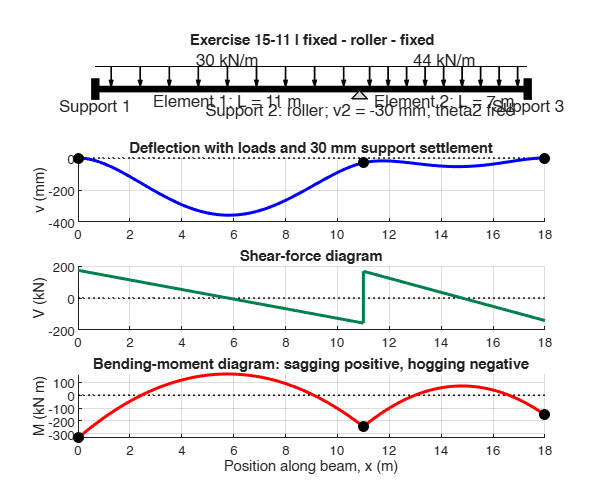

figure('Color','w','Name',exerciseName,'NumberTitle','off', ...
       'Position',[100 50 1100 900]);
spanLength = xNode(end)-xNode(1);
supportWidth = 0.018*spanLength;

subplot(4,1,1); hold on;
plot(xNode,[0 0 0],'k-','LineWidth',4);
for xWall = [xNode(1), xNode(end)]
    plot([xWall xWall],[-0.5 0.5],'k-','LineWidth',5);
end
patch(xNode(2)+[-supportWidth 0 supportWidth], ...
    [-0.45 -0.07 -0.45],[0.85 0.85 0.85],'EdgeColor','k');
for e = 1:nElement
    xLeft = xNode(connectivity(e,1));
    if q(e) ~= 0
        xArrow = linspace(xLeft+0.06*L(e),xLeft+0.94*L(e),9);
        quiver(xArrow,1.05*ones(size(xArrow)),zeros(size(xArrow)), ...
            -0.92*ones(size(xArrow)),0,'k','LineWidth',1);
        plot([xLeft xLeft+L(e)],[1.05 1.05],'k-');
        text(xLeft+L(e)/2,1.4,sprintf('%.0f kN/m',abs(q(e))), ...
            'HorizontalAlignment','center');
    end
    if P(e) ~= 0
        quiver(xLeft+a(e),1.05,0,-0.92,0,'k','LineWidth',1.8);
        text(xLeft+a(e),1.4,sprintf('%.0f kN',abs(P(e))), ...
            'HorizontalAlignment','center');
    end
    text(xLeft+L(e)/2,-0.5,sprintf('Element %d: L = %g m',e,L(e)), ...
        'HorizontalAlignment','center');
end
text(xNode(2),-0.9,supportLabel,'HorizontalAlignment','center');
text(xNode(1),-0.75,'Support 1','HorizontalAlignment','center');
text(xNode(3),-0.75,'Support 3','HorizontalAlignment','center');
xlim([xNode(1)-0.04*spanLength, xNode(end)+0.04*spanLength]);
ylim([-1.15 1.8]); axis off;
title([exerciseName, ' | fixed - roller - fixed']);

subplot(4,1,2); hold on; grid on;
plot([xNode(1) xNode(end)],[0 0],'k:');
for e = 1:nElement
    plot(xPlot{e},deflectionFactor*vPlot{e},'b-','LineWidth',1.8);
end
plot(xNode,deflectionFactor*d(1:2:5),'ko','MarkerFaceColor','k');
xlim(xNode([1 end])); ylabel(deflectionLabel);
title(deflectionTitle);

subplot(4,1,3); hold on; grid on;
plot([xNode(1) xNode(end)],[0 0],'k:');
for e = 1:nElement
    plot(xPlot{e},VPlot{e},'Color',[0 0.5 0.3],'LineWidth',1.8);
end
plot([xNode(2) xNode(2)],[VPlot{1}(end) VPlot{2}(1)], ...
    'Color',[0 0.5 0.3],'LineWidth',1.8);
xlim(xNode([1 end])); ylabel('V (kN)');
title('Shear-force diagram');

subplot(4,1,4); hold on; grid on;
plot([xNode(1) xNode(end)],[0 0],'k:');
for e = 1:nElement
    plot(xPlot{e},MPlot{e},'r-','LineWidth',1.8);
end
plot(xNode,M_support,'ko','MarkerFaceColor','k');
xlim(xNode([1 end])); xlabel('Position along beam, x (m)'); ylabel('M (kN m)');
title('Bending-moment diagram: sagging positive, hogging negative');